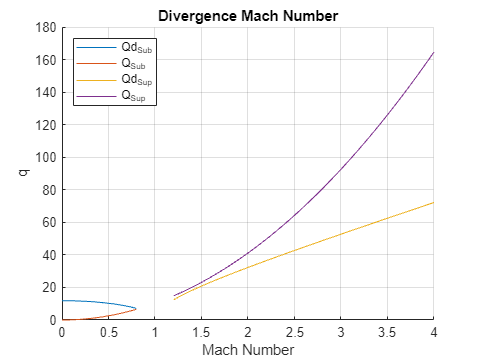

clc
clear all
k = 7000; %lbs*in
b = 100; %in
e = 25; %in
S = 22000; %in^2
p = 14.7; %psi
gamma = 1.4; %air
%by doing a match Point analysis where q (dynamic pressure) which is written as a funciton of Altitude as
%where p is the pressure (this includes the altitude information).%
% Sub-sonic Case
M_sub = linspace(0,0.8,100);
Cl_Sub = (2.*pi)./sqrt(1 - (M_sub.^2));
Qd_Sub = (0.5858 .* k .* b.^2)./(S .* e .* Cl_Sub);
Q_Sub = (gamma.*p.*(M_sub).^2)./2;
% Super-sonic case
M_sup = linspace(1.2,4,100);
Cl_Sup = (4)./sqrt((M_sup.^2) - 1);
Qd_Sup = (0.5858 .* k .* b.^2)./(S .* e .* Cl_Sup);
Q_Sup = (gamma.*p.*(M_sup).^2)./2;
% Plot
hold on
plot(M_sub,Qd_Sub,"DisplayName",'Qd_S_u_b')
plot(M_sub,Q_Sub,"DisplayName",'Q_S_u_b')
plot(M_sup,Qd_Sup,"DisplayName",'Qd_S_u_p')
plot(M_sup,Q_Sup,"DisplayName",'Q_S_u_p')
hold off
legend('Location','northwest')
xlabel('Mach Number')
ylabel('q')
title('Divergence Mach Number')
grid on